## Generate  data for pendulum

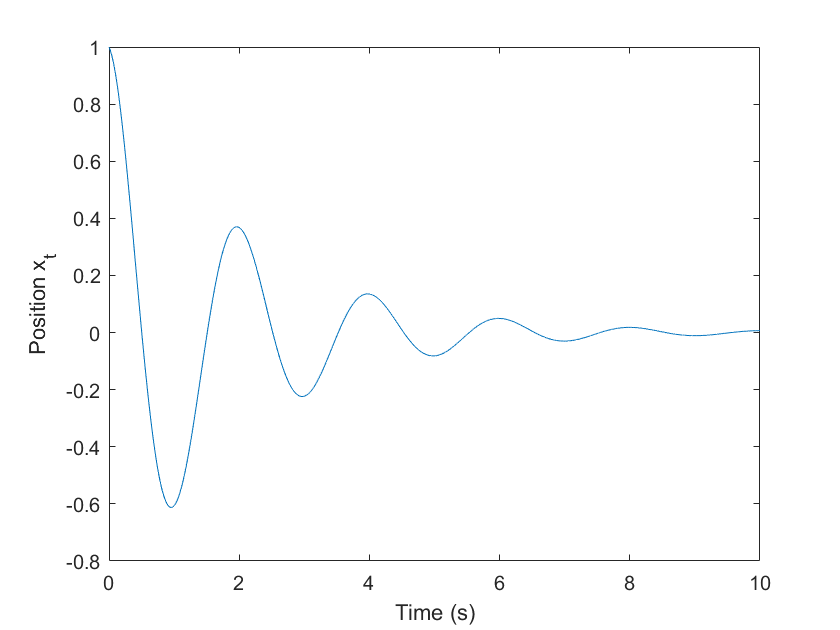

mass = 1; %m
damping= 1; % b
stiffness = 10; %K
A_0 = 1;
time_stamp = 0.000001;
time = 0:time_stamp:10; % time
delta_0=0;

omega = sqrt(stiffness/mass) * sqrt(1- damping^2/(4*mass*stiffness));

x_t = A_0*exp(-damping/(2*mass).*time).*cos(omega.*time + delta_0);


cond_time_superior_to_5 = time>=5;
observations_all = x_t (~cond_time_superior_to_5);
observations_time_all = time(~cond_time_superior_to_5);
correct_answers_all = x_t; %x_t (cond_time_superior_to_5);
questions_all = time; %time(cond_time_superior_to_5);


f1 = figure;
plot(time(1:1000:end), x_t(1:1000:end))
xlabel("Time (s)")
ylabel("Position x_t")
hold off;

%(observations, correct_answers, questions)
observations = reshape(observations_all, [1,1,1, length(observations_all)]);
observations = dlarray(observations, 'SSCB');


observations_time = reshape(observations_time_all, [1,1,1, length(observations_time_all)]);
observations_time = dlarray(observations_time, 'SSCB');

n_step_per_sequence = 50;
assert ( (mod(length(observations),n_step_per_sequence)==0), "the number of sample is not divisible by " + string(n_step_per_sequence));

%observations
observations = reshape(observations,1,1, n_step_per_sequence, []);
observations_time = reshape(observations_time,1,1, n_step_per_sequence, []);


all_possible_questions = reshape(questions_all, [1,1,1, length(questions_all)]);
all_possible_questions = dlarray(all_possible_questions, 'SSCB');
numOfPossibleQuestions = size(all_possible_questions,4);

all_possible_correct_answers = reshape(correct_answers_all, [1,1,1, length(correct_answers_all)]);
all_possible_correct_answers = dlarray(all_possible_correct_answers, 'SSCB');



%Creation of triplets : (observation, questions, correct_answers)
%% observations: already compute above
numObservations = size(observations,4);
%Select 'numObservations' randomly questions and their associates correct answers
idx_select = randperm(numOfPossibleQuestions,numObservations); 


questions = all_possible_questions(:,:,:, idx_select);
correct_answers = all_possible_correct_answers(:,:,:, idx_select);


idx_end_train = floor(0.95*numObservations);
XTrain = observations(:,:,:, 1:idx_end_train);
questionsTrain = questions(:,:,:, 1:idx_end_train);
YTrain = correct_answers (:,:,:, 1:idx_end_train); 
XTrain_time = observations_time(:,:,:, 1:idx_end_train); %not required

numTrainImages = size(XTrain,4);
XTest = observations(:,:,:, idx_end_train+1:end);
YTest = correct_answers (:,:,:, idx_end_train+1:end);
questionsTest =  questions(:,:,:, idx_end_train+1:end);
XTest_time= observations_time(:,:,:, idx_end_train+1:end); %not required

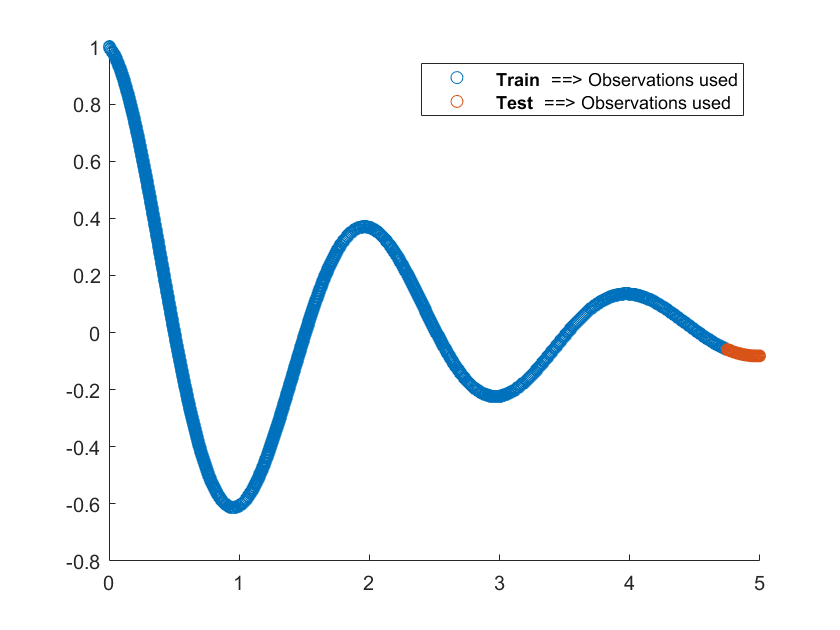

figure
t = XTrain_time.extractdata();
t= reshape(t, 1, []);
x= XTrain.extractdata();
x= reshape(x, 1, []);
scatter (t,x, "DisplayName", "\bf Train \rm ==> Observations used")
hold on
t = XTest_time.extractdata();
t= reshape(t, 1, []);
x= XTest.extractdata();
x= reshape(x, 1, []);
scatter (t,x, "DisplayName", "\bf Test \rm ==> Observations used")
legend()
hold off

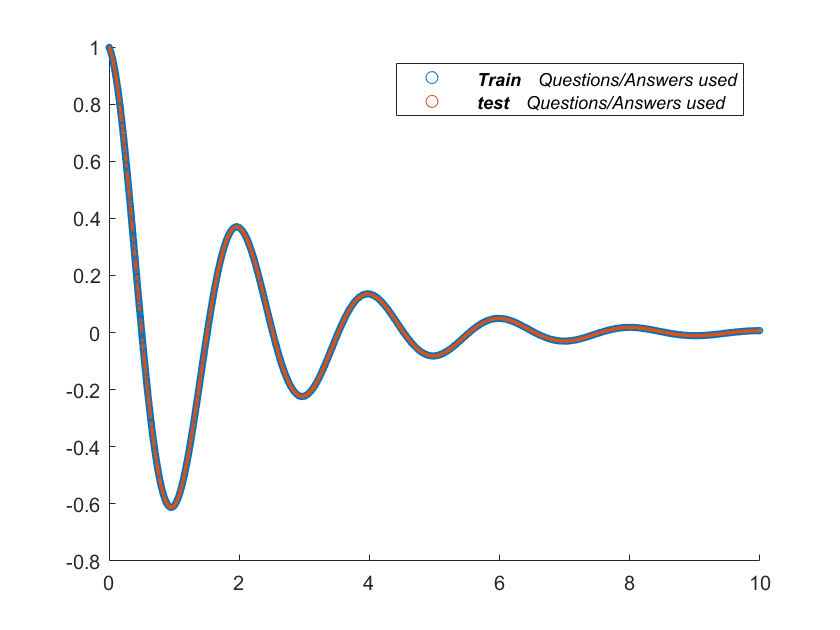


figure
t = questionsTrain.extractdata();
t= reshape(t, 1, []);
x= YTrain.extractdata();
x= reshape(x, 1, []);
scatter (t,x, 10, "DisplayName", "\it \bf Train \rm \it Questions/Answers used")
hold on
t = questionsTest.extractdata();
t = reshape(t, 1, []);
x = YTest.extractdata();
x = reshape(x, 1, []);
scatter (t,x,2, "DisplayName", "\it \bf test \rm \it Questions/Answers used")
legend()
hold off

## Construct Network

Autoencoders have two parts: the encoder and the decoder. The encoder takes an image input and outputs a compressed representation (the encoding), which is a vector of size `latent_dim`. The decoder takes the compressed representation, decodes it, and recreates the original image.

To make calculations more numerically stable, increase the range of possible values from [0,1] to [-inf, 0] by making the network learn from the logarithm of the variances. Define two vectors of size `latent_dim`: one for the means $\mu$ and one for the logarithm of the variances $\log \left(\sigma^2 \right)$. Then use these two vectors to create the distribution to sample from. 

latentDim = 3;
imageSize = [1 1 n_step_per_sequence];


encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    fullyConnectedLayer(500, 'Name', 'fc_encoder1')
    eluLayer('Name','e')
    fullyConnectedLayer(100, 'Name', 'fc_encoder2')
    eluLayer('Name','elu2')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoderOutput')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim+1],'Name','i','Normalization','none')
    fullyConnectedLayer(100, 'Name', 'fc_decoder1')
    eluLayer('Name','elu1')
    fullyConnectedLayer(100, 'Name', 'fc_decoder2')
    eluLayer('Name','elu2')
    fullyConnectedLayer(1, 'Name', 'fc_decoderOutput')
    ]);



To train both networks with a custom training loop and enable automatic differentiation, convert the layer graphs to `dlnetwork` objects.

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

## Define Model Gradients Function

The helper function modelGradients takes in the encoder and decoder `dlnetwork` objects and a mini-batch of input data `X`, and returns the gradients of the loss with respect to the learnable parameters in the networks. This helper function is defined at the end of this example.

The function performs this process in two steps: sampling and loss. The sampling step samples the mean and the variance vectors to create the final encoding to be passed to the decoder network. However, because backpropagation through a random sampling operation is not possible, you must use the *reparameterization trick*. This trick moves the random sampling operation to an auxiliary variable $\varepsilon$, which is then shifted by the mean $\mu_i$ and scaled by the standard deviation $\sigma_i$. The idea is that sampling from $N\left(\mu_i ,\sigma_i^2 \right)$ is the same as sampling from $\mu_i +\varepsilon \cdot \sigma_i$, where  $\varepsilon \sim N\left(0,1\right)$. The following figure depicts this idea graphically.

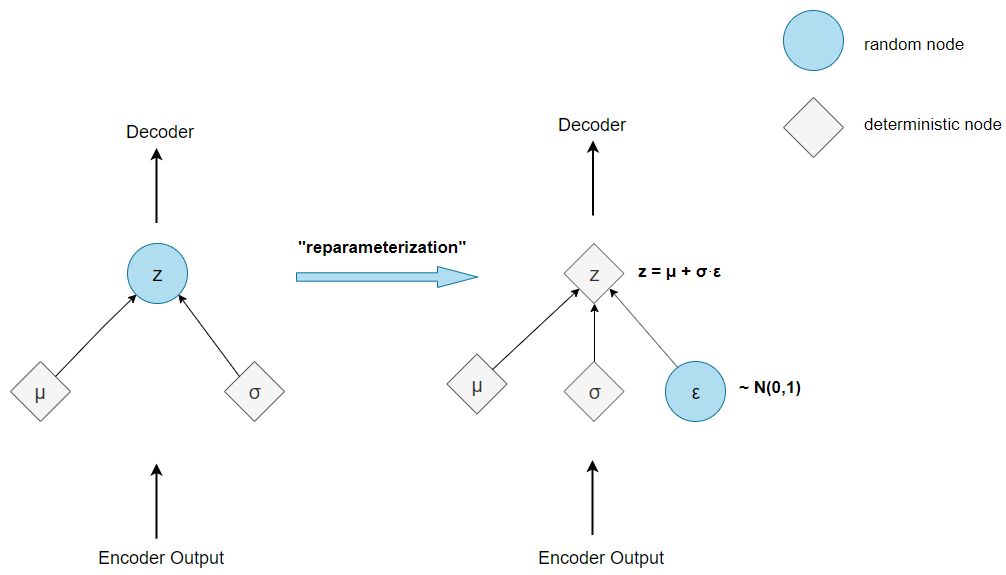

The loss step passes the encoding generated by the sampling step through the decoder network, and determines the loss, which is then used to compute the gradients. The loss in VAEs, also called the evidence lower bound (ELBO) loss, is defined as a sum of two separate loss terms:

$\textrm{ELBO}\;\textrm{loss}=\textrm{reconstruction}\;\textrm{loss}+\textrm{KL}\;\textrm{loss}$.

The *reconstruction loss* measures how close the decoder output is to the original input by using the mean-squared error (MSE):

$\textrm{reconstruction}\;\textrm{loss}=\textrm{MSE}\left(\textrm{decoder}\;\textrm{output},\textrm{original}\;\textrm{image}\right)$.

The *KL loss*, or Kullback–Leibler divergence, measures the difference between two probability distributions. Minimizing the KL loss in this case means ensuring that the learned means and variances are as close as possible to those of the target (normal) distribution. For a latent dimension of size $n$, the KL loss is obtained as

$\textrm{KL}\;\textrm{loss}=-0\ldotp 5\cdot \sum_{i=1}^n \left(1+\log \left(\sigma_i \right)-\mu_i^2 -\sigma_i^2 \right)$.

The practical effect of including a KL loss term is to pack the clusters learned due to the reconstruction loss tightly around the center of the latent space, forming a continuous space to sample from.

## Loss function used for SciNet

The $\beta -\textrm{VAE}$ loss is a modification of ELBO loss with a multiplier $\beta \;$. if $\beta =1$ then, it is same as VAE   


$$\left.\left.L_{\textrm{BETA}} \left(\phi ,\beta \right)=-E_{\left.z\;\sim q_{\phi } \left(z\right|x\right)} {\log \;p}_{\theta } \left(x\right|z\right)+\beta D_{\textrm{KL}} \left(q_{\phi } \left(z\right|x\right)\parallel p_{\theta } \left(z\right)\right)$$


## Specify Training Options

Train on a GPU (requires Parallel Computing Toolbox™). If you do not have a GPU, set the `executionEnvironment` to `"cpu"`.

executionEnvironment = "auto";

Set the training options for the network. When using the Adam optimizer, you need to initialize for each network the trailing average gradient and the trailing average gradient-square decay rates with empty arrays`.`

numEpochs = 4;%1000
miniBatchSize = 512;
lr = 1e-3;
numIterations = floor(numTrainImages/miniBatchSize);
iteration = 0;

avgGradientsEncoder = [];
avgGradientsSquaredEncoder = [];
avgGradientsDecoder = [];
avgGradientsSquaredDecoder = [];

## Train Model

Train the model using a custom training loop.

For each iteration in an epoch:

- Obtain the next mini-batch from the training set.

- Convert the mini-batch to a `dlarray` object, making sure to specify the dimension labels `'SSCB'` (spatial, spatial, channel, batch).

- For GPU training, convert the `dlarray` to a `gpuArray` object.

- Evaluate the model gradients using the `dlfeval `and` modelGradients `functions.

- Update the network learnables and the average gradients for both networks, using the `adamupdate` function.

At the end of each epoch, pass the test set images through the autoencoder, and display the loss and the training time for that epoch.

for epoch = 1:numEpochs
    tic;
    for i = 1:numIterations
        iteration = iteration + 1;
        idx = (i-1)*miniBatchSize+1:i*miniBatchSize;
        XBatch = XTrain(:,:,:,idx);
        YBatch = YTrain(:,:,:,idx);
        questionsBatch = questionsTrain(:,:,:,idx);
   
        XBatch = dlarray(single(XBatch), 'SSCB');
        YBatch = dlarray(single(YBatch), 'SSCB');
        questionsBatch = dlarray(single(questionsBatch), 'SSCB');
        
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            XBatch = gpuArray(XBatch);    
            YBatch = gpuArray(YBatch);    
        end 
            
        [infGrad, genGrad] = dlfeval(...
            @modelGradients, encoderNet, decoderNet, XBatch,questionsBatch, YBatch);
        
        [decoderNet.Learnables, avgGradientsDecoder, avgGradientsSquaredDecoder] = ...
            adamupdate(decoderNet.Learnables, ...
                genGrad, avgGradientsDecoder, avgGradientsSquaredDecoder, iteration, lr);
        [encoderNet.Learnables, avgGradientsEncoder, avgGradientsSquaredEncoder] = ...
            adamupdate(encoderNet.Learnables, ...
                infGrad, avgGradientsEncoder, avgGradientsSquaredEncoder, iteration, lr);
    end
    elapsedTime = toc;
    
    XTest_ = dlarray(single(XTest), 'SSCB');
    [z, zMean, zLogvar] = sampling(encoderNet, XTest_);
    decoderinput = cat(3, z, questionsTest);
    yPred = sigmoid(forward(decoderNet, decoderinput));
    betavaeloss = betaVAEloss(YTest, yPred, zMean, zLogvar);
    
    disp("Epoch : "+epoch+" Test betaVAE loss = "+gather(extractdata(betavaeloss))+...
        ". Time taken for epoch = "+ elapsedTime + "s")    
end

Epoch : 1 Test betaVAE loss = 0.021223. Time taken for epoch = 16.3791s
Epoch : 2 Test betaVAE loss = 0.016125. Time taken for epoch = 13.2684s
Epoch : 3 Test betaVAE loss = 0.015239. Time taken for epoch = 11.9027s
Epoch : 4 Test betaVAE loss = 0.015113. Time taken for epoch = 11.278s


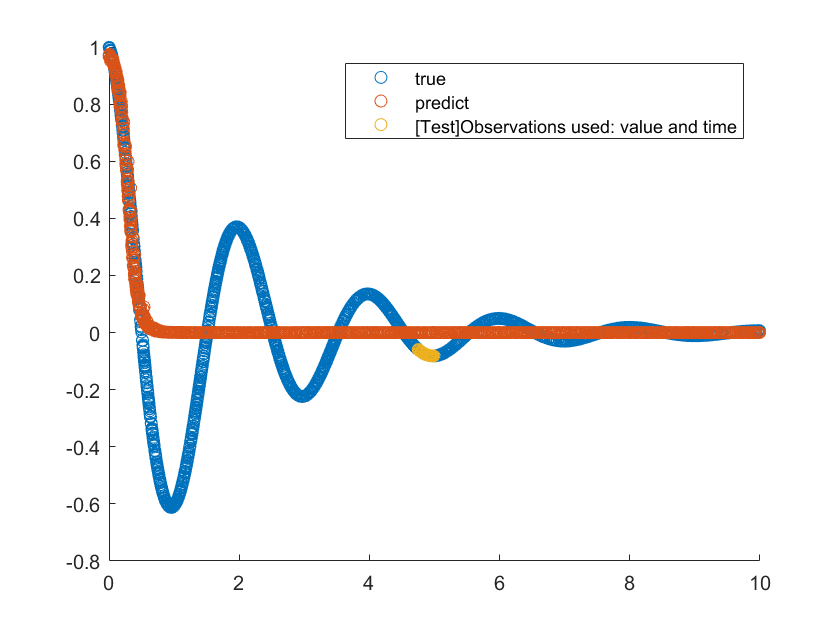

% try to make prediction

XTest_ = dlarray(single(XTest), 'SSCB');
XTest_time_ = dlarray(single(XTest_time), 'SSCB');
[z, ~, ~] = sampling(encoderNet, XTest_);
decoderinput = cat(3, z, questionsTest);
yPred = sigmoid(forward(decoderNet, decoderinput));

true_val = YTest.extractdata();
pred_val= yPred.extractdata();
questions_val = questionsTest.extractdata();

true_val = reshape(true_val, 1, []);
pred_val = reshape(pred_val, 1, []);
questions_val = reshape(questions_val, 1, []);

figure
scatter(questions_val, true_val, "DisplayName", 'true');
hold on
scatter(questions_val, pred_val, "DisplayName", 'predict');
scatter(reshape(XTest_time_.extractdata(), 1, []), reshape(XTest_.extractdata(), 1, []), "DisplayName", '[Test]Observations used: value and time');
legend
hold off

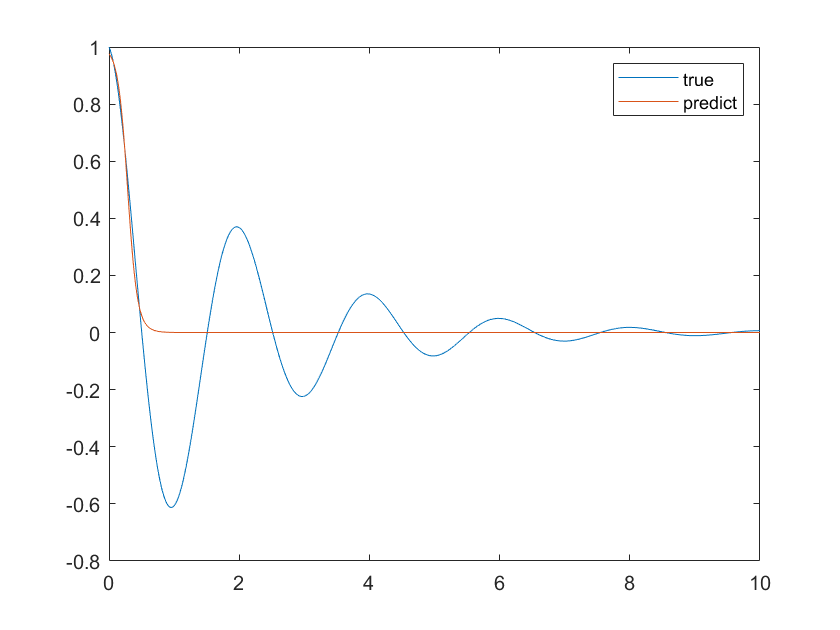

%Using all_possible_questions and all_possible_correct_answers

XTest_ = dlarray(single(XTest), 'SSCB');
[z, zMean, zLogvar] = sampling(encoderNet, XTest_(:,:,:,1));

num_questions= size(all_possible_questions,4);
zinput= repmat(z,1,1,1,num_questions);
decoderinput = cat(3, zinput, all_possible_questions);
yPred = sigmoid(forward(decoderNet, decoderinput));

true_val = all_possible_correct_answers.extractdata();
pred_val= yPred.extractdata();
questions_val = all_possible_questions.extractdata();

true_val = reshape(true_val, 1, []);
pred_val = reshape(pred_val, 1, []);
questions_val = reshape(questions_val, 1, []);

ftest = figure;
plot(questions_val, true_val, "DisplayName", 'true');
hold on
plot(questions_val, pred_val, "DisplayName", 'predict');
legend
hold off

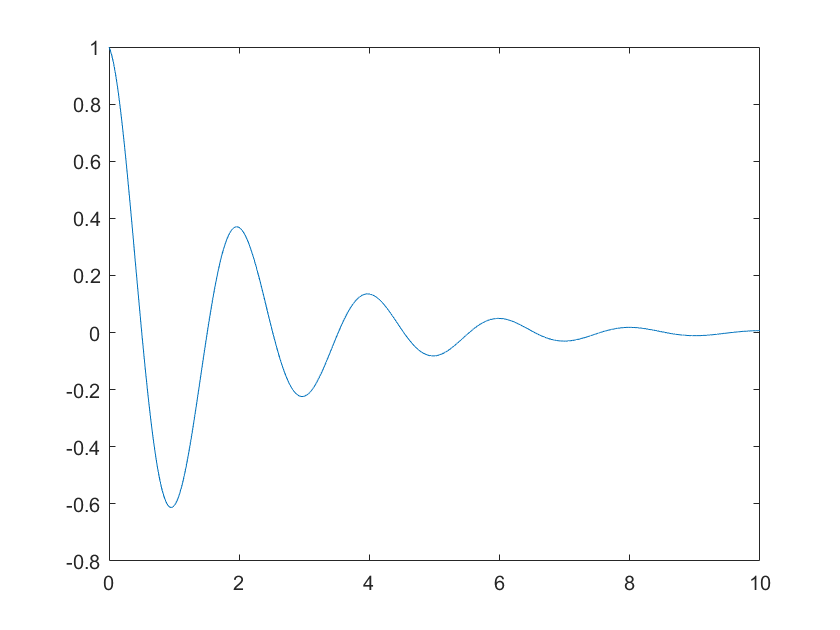

plot(questions_val(1:1000:end), true_val(1:1000:end))

## Helper Functions

### Model Gradients Function

The `modelGradients` function takes the encoder and decoder `dlnetwork` objects and a mini-batch of input data `X`, and returns the gradients of the loss with respect to the learnable parameters in the networks. The function performs three operations:

- Obtain the encodings by calling the `sampling `function on the mini-batch of images that passes through the encoder network.

- Obtain the loss by passing the encodings through the decoder network and calling the betaVAEloss function.

- Compute the gradients of the loss with respect to the learnable parameters of both networks by calling the `dlgradient` function.

function [infGrad, genGrad] = modelGradients(encoderNet, decoderNet, x, question, ytrue)
[z, zMean, zLogvar] = sampling(encoderNet, x);
decoder_input = cat(3, z, question);
yPred = sigmoid(forward(decoderNet, decoder_input));
loss = betaVAEloss(ytrue, yPred, zMean, zLogvar);
[genGrad, infGrad] = dlgradient(loss, decoderNet.Learnables, ...
    encoderNet.Learnables);
end

### Sampling and Loss Functions

The `sampling` function obtains encodings from input images. Initially, it passes a mini-batch of images through the encoder network and splits the output of size (`2*latentDim)*miniBatchSize` into a matrix of means and a matrix of variances, each of size `latentDim*batchSize`. Then, it uses these matrices to implement the reparameterization trick and to compute the encoding. Finally, it converts this encoding to a `dlarray` object in SSCB format.

function [zSampled, zMean, zLogvar] = sampling(encoderNet, x)
compressed = forward(encoderNet, x);
d = size(compressed,1)/2;
zMean = compressed(1:d,:);
zLogvar = compressed(1+d:end,:);

sz = size(zMean);
epsilon = randn(sz);
sigma = exp(.5 * zLogvar);
z = epsilon .* sigma + zMean;
z = reshape(z, [1,1,sz]);
zSampled = dlarray(z, 'SSCB');
end

The betaVAEloss function takes the encodings of the means and the variances returned by the `sampling `function, and uses them to compute the $\beta -\textrm{VAE}$ loss.

function betavaeloss = betaVAEloss(x, xPred, zMean, zLogvar)
squares = 0.5*(xPred-x).^2;
reconstructionLoss  = sum(squares, [1,2,3]);

beta = 0.001; % beta=1 ==> same as VAE
KL = -beta/2 * sum(1 + zLogvar - zMean.^2 - exp(zLogvar), 1);

betavaeloss = mean(reconstructionLoss + KL);
end

*Copyright 2019 The MathWorks, Inc.*